# Problem 2: Aerobraking

Student 1: _________

Student 2: _________

Data of the problem:

clear all;
mu = 42828.4; % mu Mars, km^3/s^2 
RM = 3389.9;   % km

a = 5940;                       % Semi-major axis [km]
e= 0.4;                         % Eccentricity 
Omega = deg2rad(194);           % RAAN 
i = deg2rad(56);                % Inclination 
omega = deg2rad(258);           % Argument of perigee 

theta_0 = deg2rad(230);         % True anomaly at t=0 
S = 10;                         % Shield area [m^2]
m = 3000;                       % Mass of the spacecraft [kg]


## Initial position and velocity vectors

X = coe2stat([a,e,i,Omega,omega,theta_0],mu);


## Ideal 2BP Cowell propagation and convergence study

For different values of $\delta t$

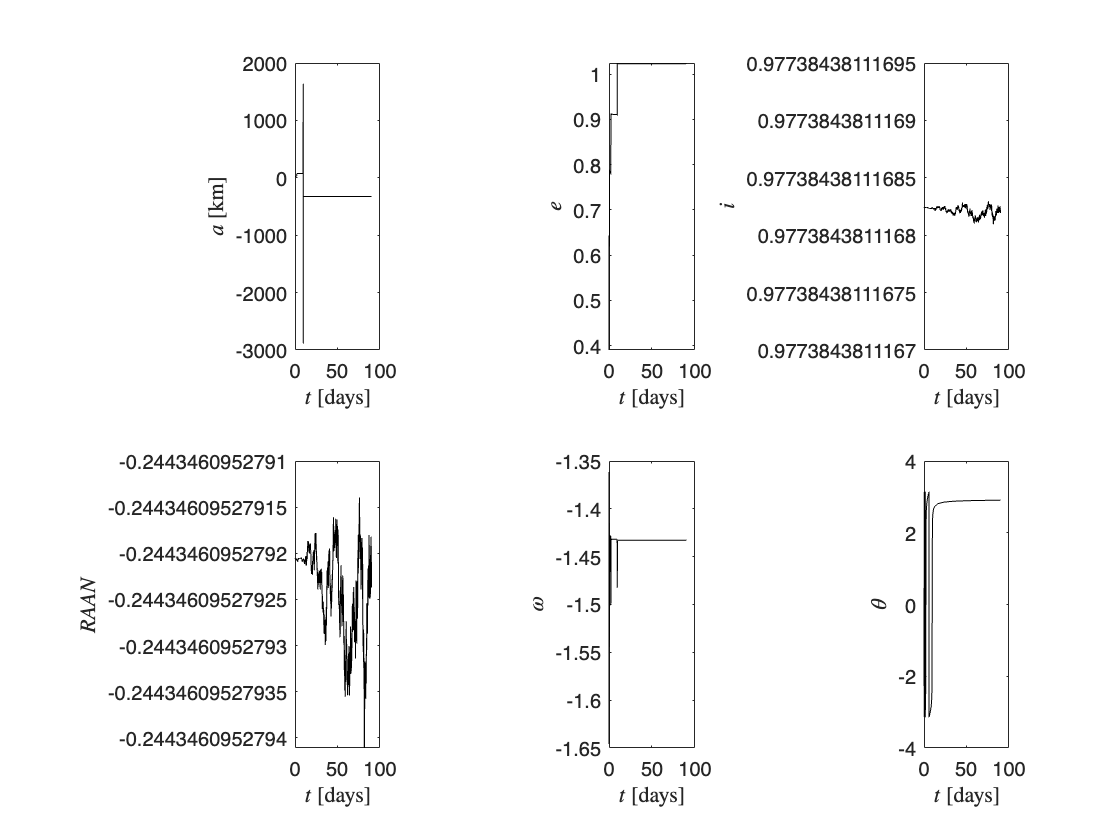

flag = false;
tf = 90*24*3600;

dt1 = 300;
t1 = 0:dt1:tf;
X1 = RK4(X,dt1,flag);

for j =1:length(X1)
    coe1(:,j) = stat2coe(X1(:,j),mu); 
end


figure(1)
plot_orbit(t1,coe1)

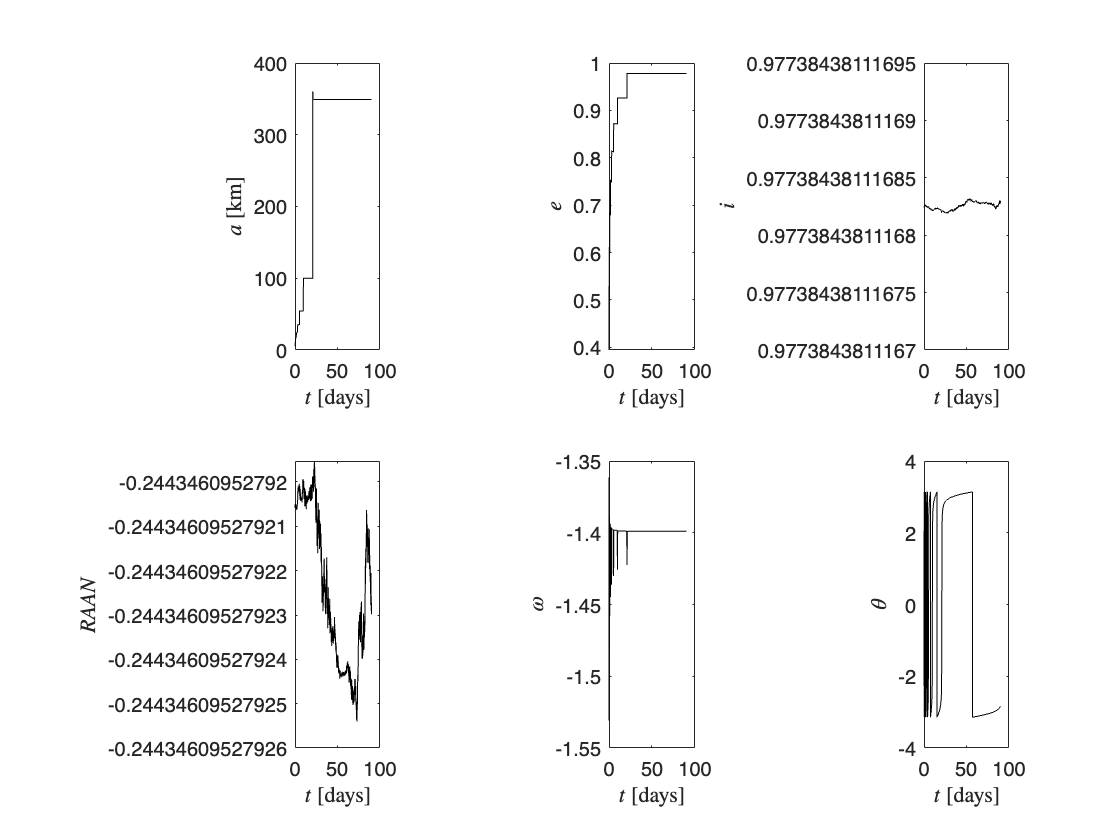


dt2 = 150; 
t2 = 0:dt2:tf;
X2 = RK4(X,dt2,flag);

for j =1:length(X2)
    coe2(:,j) = stat2coe(X2(:,j),mu); 
end

figure(2)
plot_orbit(t2,coe2)

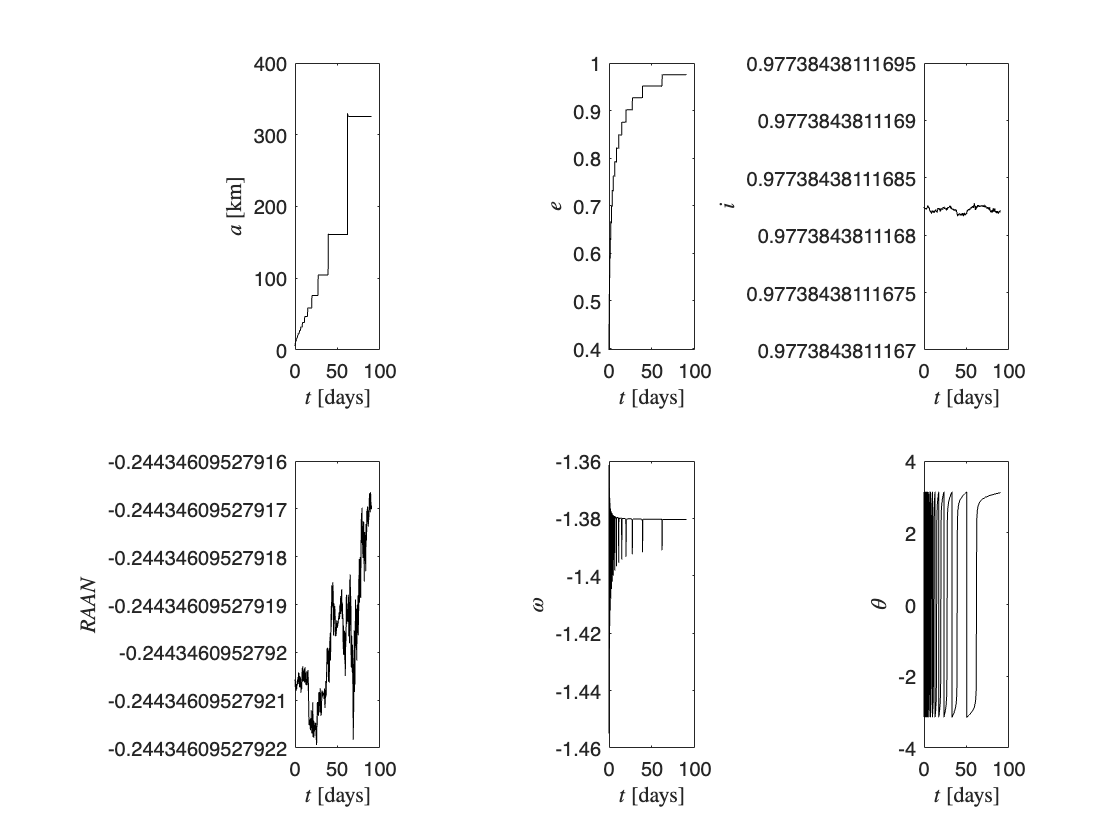


dt3 = 75;
t3 = 0:dt3:tf; 
X3 = RK4(X,dt3,flag);

for j =1:length(X3)
    coe3(:,j) = stat2coe(X3(:,j),mu); 
end

figure(3)
plot_orbit(t3,coe3)

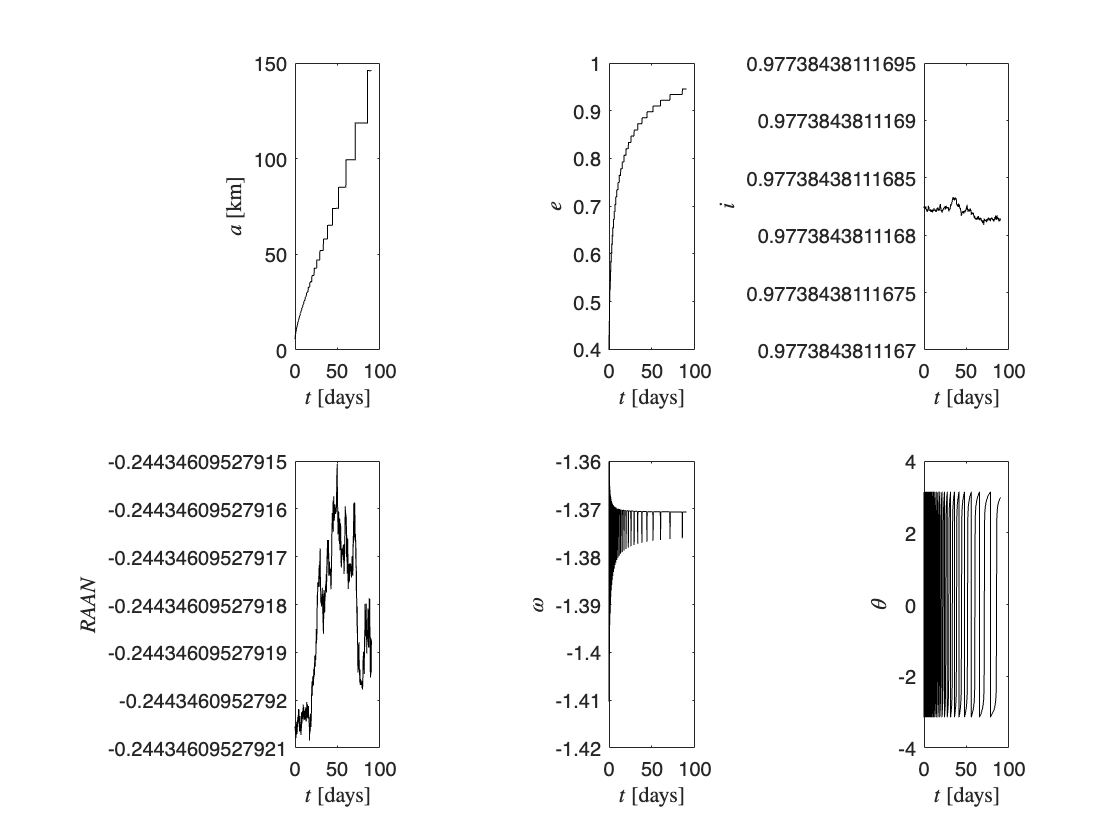


dt4 = 37.5;
t4 = 0:dt4:tf;
X4 = RK4(X,dt4,flag);

for j =1:length(X4)
    coe4(:,j) = stat2coe(X4(:,j),mu); 
end

figure(4)
plot_orbit(t4,coe4)

And you can add more code/text blocks as needed.

## Perturbed 2BP Cowell propagation

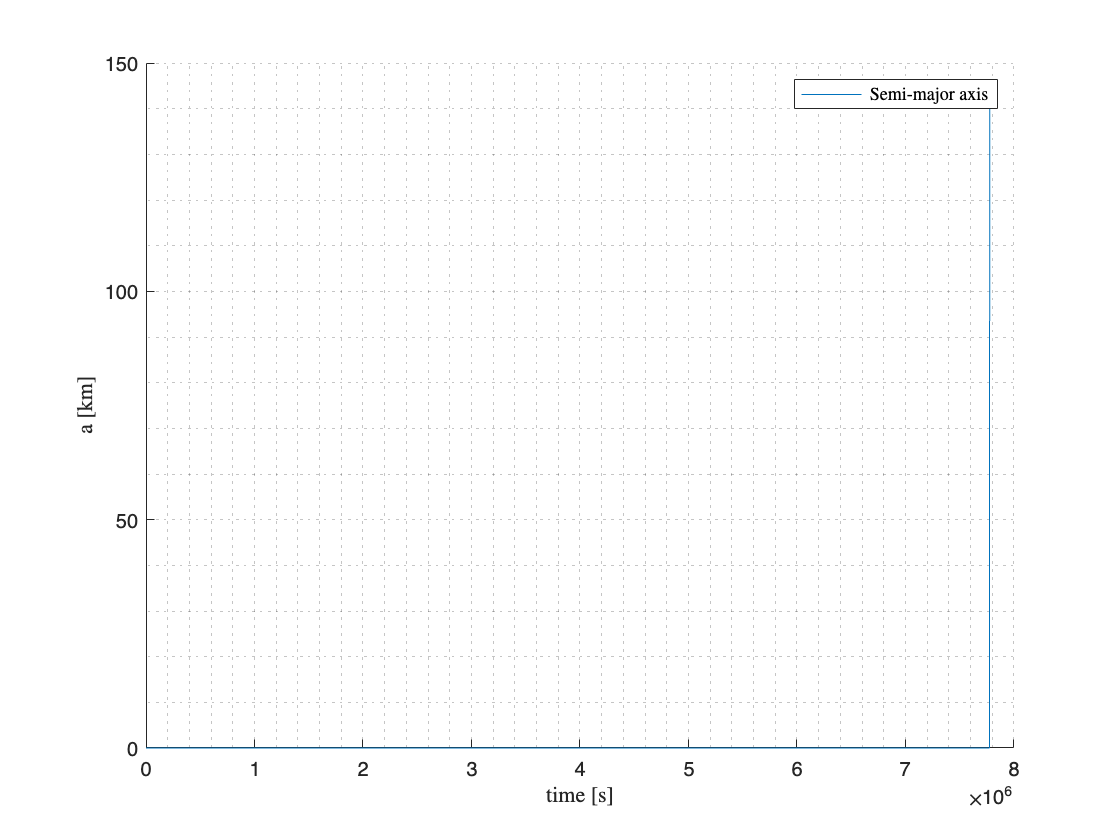

X4_2 = RK4(X,dt4,true);

for k=1:length(X4_2(1,:))
    if norm(X4_2(1:3,k))<50
        return
    end
    coe4_2(:,j) = stat2coe(X4_2(:,j),mu);
end


figure 
hold on
grid minor
plot(t4,coe4_2(1,:)/1000)
legend('Semi-major axis',Interpreter='latex')
xlabel('time [s]',Interpreter='latex')
ylabel('a [km]',Interpreter='latex')
hold off

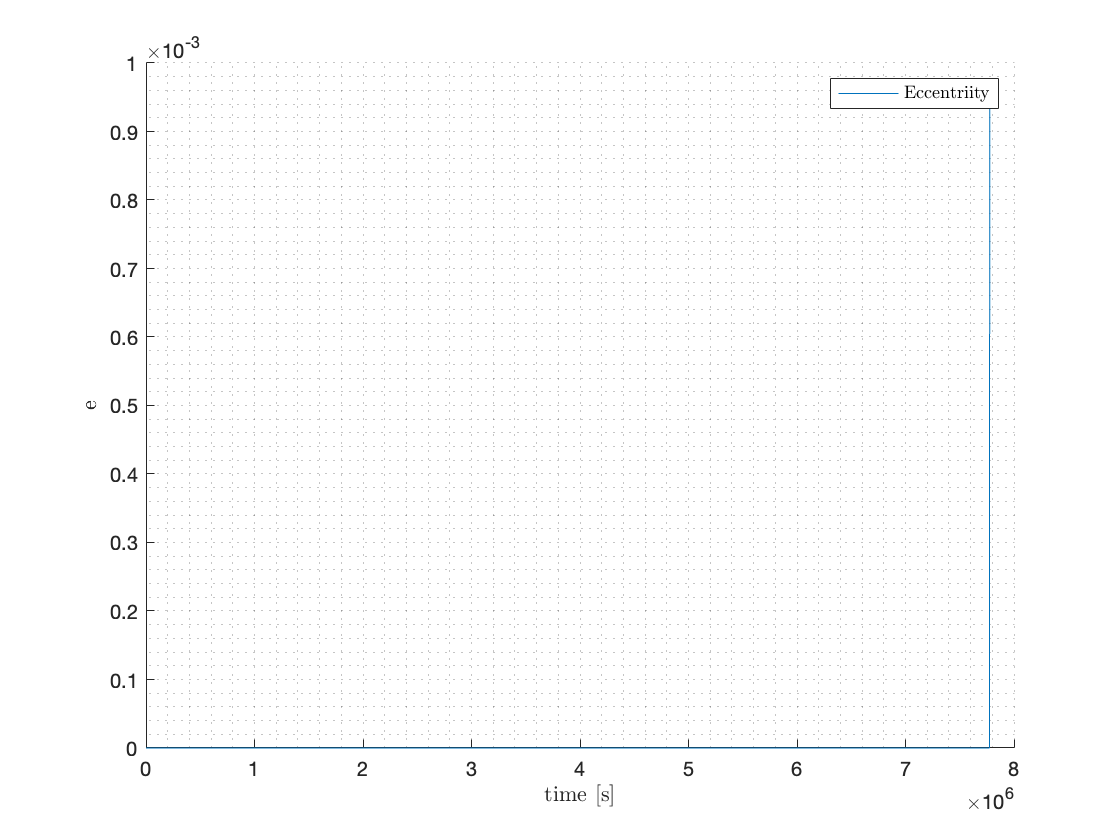


figure 
hold on
grid minor
plot(t4,coe4_2(2,:)/1000)
legend('Eccentriity',Interpreter='latex')
ylabel('e',Interpreter='latex')
xlabel('time [s]',Interpreter='latex')
hold off

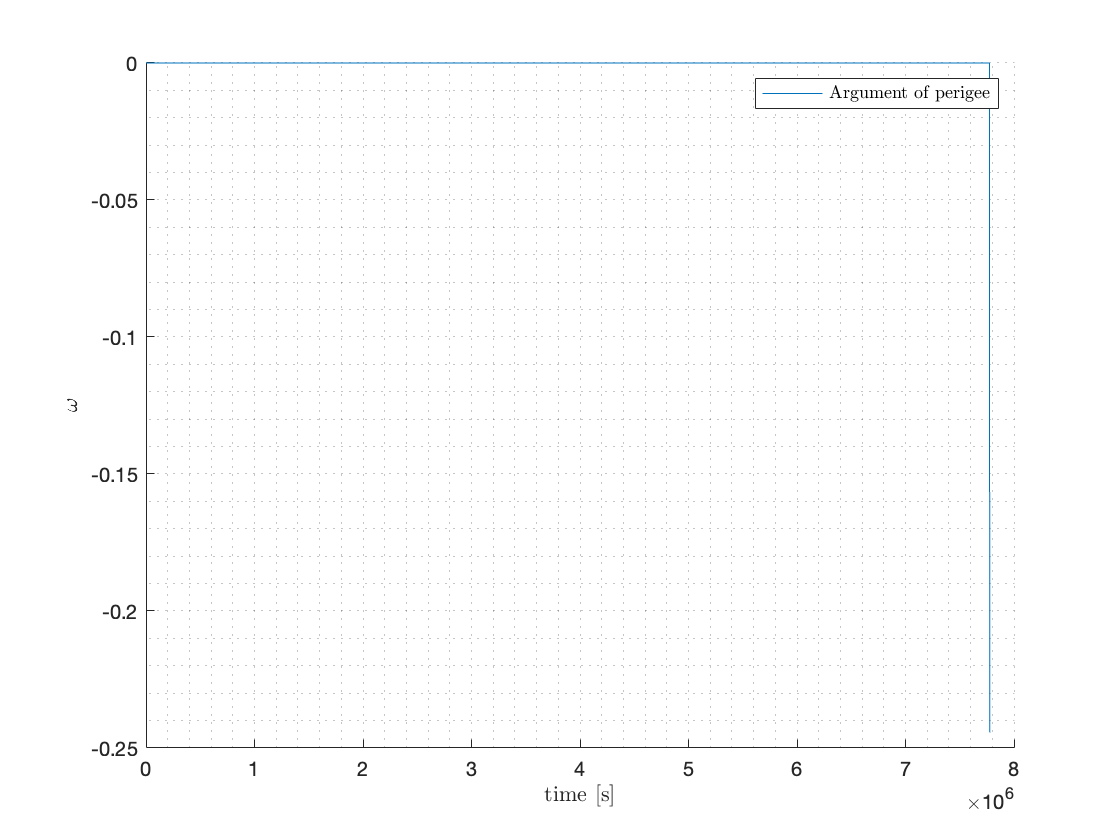


figure 
hold on
grid minor
plot(t4,coe4_2(4,:))
legend('Argument of perigee',Interpreter='latex')
ylabel('$\omega$',Interpreter='latex')
xlabel('time [s]',Interpreter='latex')
hold off

## Time to reentry

% ...

## Discussion

(Complete your report with any comments you may like to add)